**Using the CellTyper MATLAB app**

Purpose. CellTyper allows you to view graphs from several key datasets for cell-attached recordings of RGCs that you can compare to those at [rgctypes.org](http://rgctypes.org) to help you determine RGC types. You can assign a cell to a new type from within the App.

Launching the App.

There are two ways to launch CellTyper. The first way is to just call it with no arguments from the command line:

The second method is to initialize it with a list of cells you want to examine.

where cell_id_list is a cell array of cell names. The following code will open CellTyper on the set of all OFF sustained alpha RGCs in the database.

OFFsA = sl_mutable.CurrentCellType & 'cell_type = "OFF sustained alpha"';
cell_list = OFFsA.fetchn('cell_id');
CellTyper(cell_list);

You should now see a screen that looks like this:

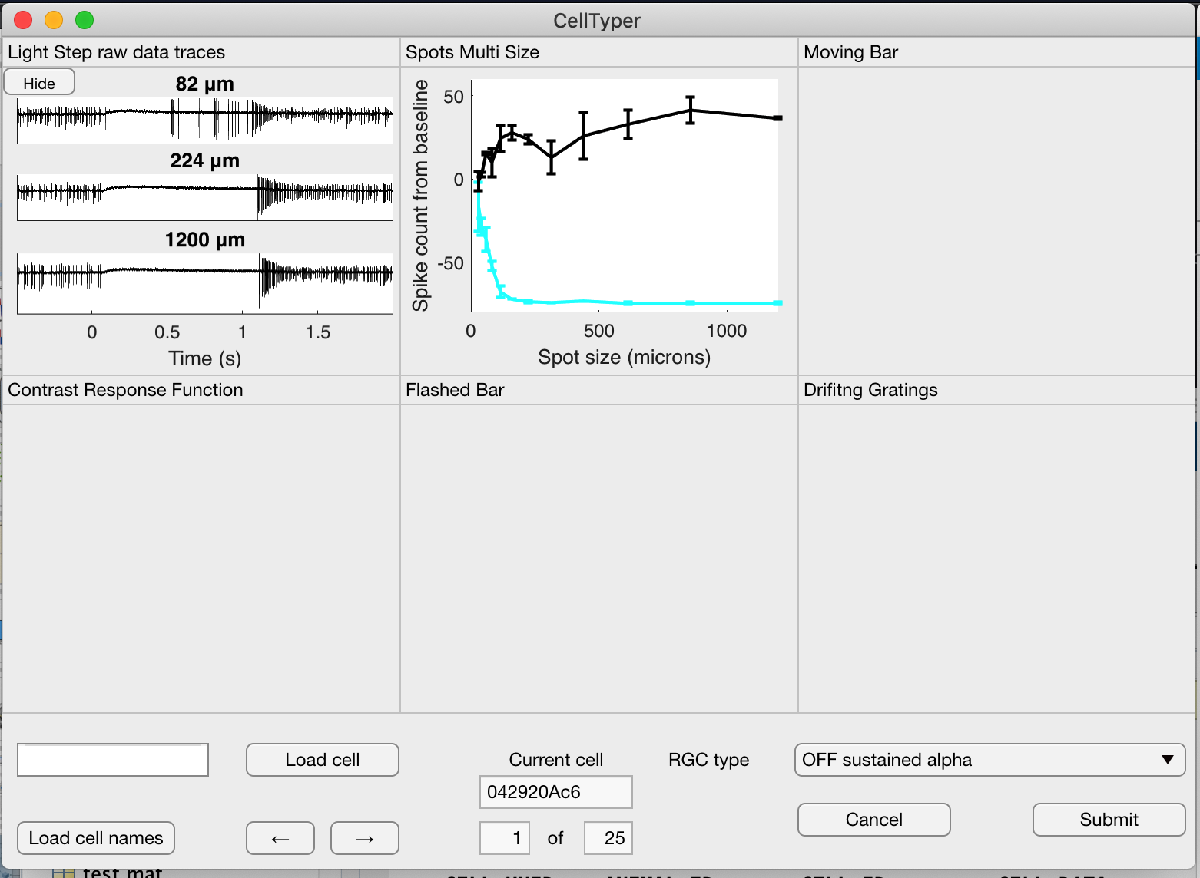

Each of the 6 panels shows plots for different types of datasets. If a dataset does not exist for this cell, has not been analyzed, or causes a plotting error, it will not be displayed, 

You can scroll though cells with the arrow buttons, and it will update to display the current cell ID and the number out of the total in your list. 

Loading cells.

You can load a single cell by typing its cell_id into the blank edit field on the left side and then pressing the "Load cell" button. Note: this will replace the currently loaded list.

You can also load a set of cells from a .txt file in which each cell name is on its own line. To do this, press the "Load cell names" button. This will open up a dialog box to select a .txt file. If a file is selected, it will replace the currently loaded list.

Assigning cell types.

The currently assigned RGC type will appear in the drop-down menu on the right. "Unknown" is one of the types. To change the cell type, simply choose a new type from the menu and press "Submit". The "Cancel" button will close the app without changing the current cell type, but all the previous ones you have changed will remain changed. 

Note: In datajoint, we will now have a record of the full history of our cell type assignemnts. When you submit an assignment, it adds a time-stamped and user-stamped event to the log and replaces the entry in the sl_mutable.CurrentCellType table. So if you get it wrong or are not sure, that is ok. We can always change it again. 

Buttons in the plot panels.

Some plot panels have a hide/show button that you can use to hide or show the plot. The light-step traces take a bit longer to draw than the other plots, so the App will run somewhat faster with them hidden. Other panels have arrow buttons if the current cell has more than one dataset of the matching type or more than one set of paramters per dataset (for DriftingGratings). You can use the arrows tp scroll through the different plots, and some information about the key parameters that are different in each plot should appear in the plot title.